## Reading global specs file

filename = 'global_specs.txt';
params = ReadFile(filename);

Non-comment lines:
    {'wav'}    {'animal_call.wav'}    {'20000'}    {'tone'}    {'10000'}    {'3'}    {'0.5'}    {'1000, 2000, 4000, 8000'}    {'0.5'}    {'hann'}    {'50'}    {'iir'}    {'2'}    {'butterworth'}    {'lp'}    {'1000'}    {'2'}    {'1'}    {'log'}    {'log'}    {'nyquist'}    {'40'}

Chosen signal:
wav
Filename:
animal_call.wav
Target sampling frequency:
       20000

Generated signal type:
tone
Generator sampling frequency:
       10000

Generated signal duration:
     3

Spectral resolution:
    0.5000

Window type:
hann
Overlap:
    50

Filtering method:
iir
Filter order:
     2

Approximation method:
butterworth
Filter type:
lp
Cut-off frequencies:
        1000

X-axis time limit:
     2

Y-axis amplitude limit:
     1

X-axis scaling:
log
Y-axis scaling:
log
X-axis frequency limit:
       10000

Y-axis spectral amplitude limit:
    40



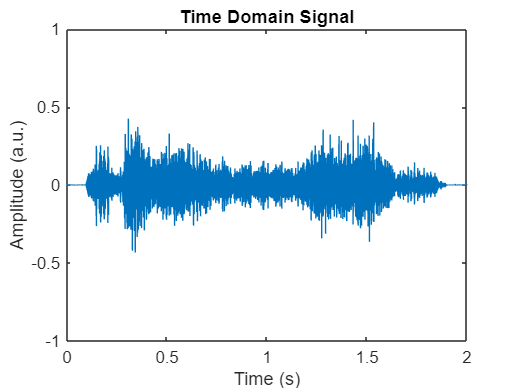

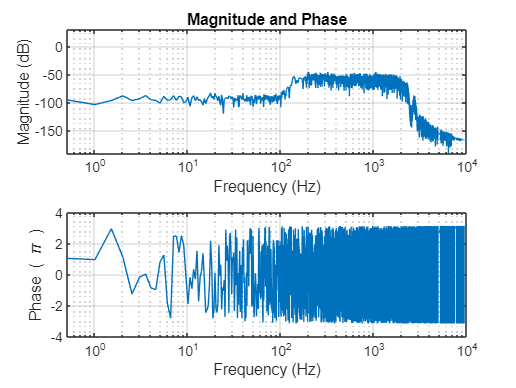

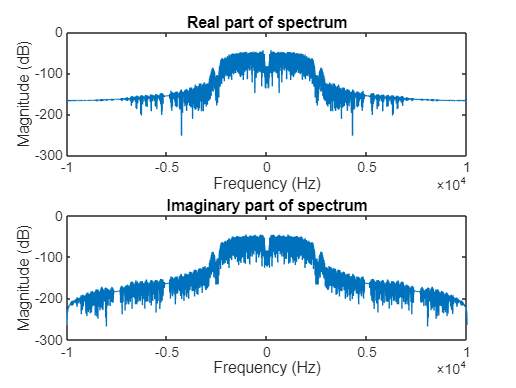

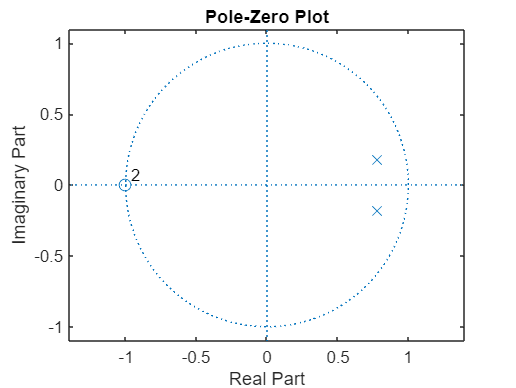

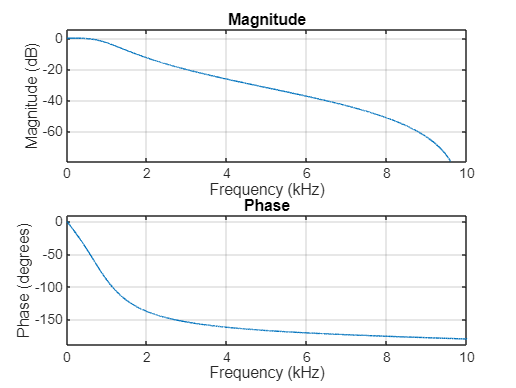

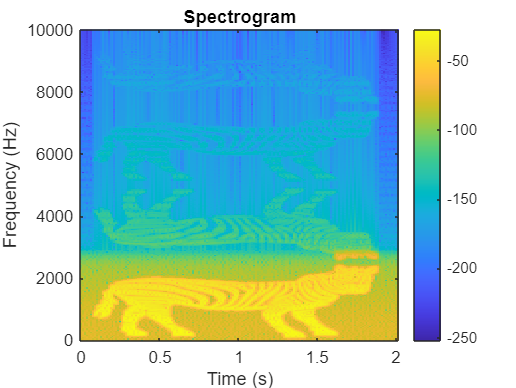

if strcmp(params.chosen_signal,'generate')
    [signal,t]=generate_signal1(params);
    Fs=params.generator_fs;
    audiowrite("inputsignal_generated.wav", signal, Fs);
end
if strcmp(params.chosen_signal,'wav')
    filePath = params.filename;
    [signal, Fs] = audioread(filePath);
    signal=resample(signal,params.target_fs,Fs);
    Fs=params.target_fs;
    t=0:1/Fs:length(signal)*(1/Fs)-(1/Fs);
end
[B, A] = design_filter(params, 0.5, Fs);
signal = filter(B, A, signal);
audiowrite("outputsignal.wav", signal, Fs);
[DFT_Y, DFT_f, STFT_Y, STFT_f, STFT_t]=frequency_analyser(signal, params, 40, Fs, -inf);
plotting(signal, t, B, A, DFT_Y, DFT_f, STFT_Y, STFT_t, STFT_f, params, Fs)


% Save numerator coefficients
save('numerator_coefficients.txt', 'B', '-ascii');

% Save denominator coefficients
save('denominator_coefficients.txt', 'A', '-ascii');

## Storing data as ASCII and plots as pdf

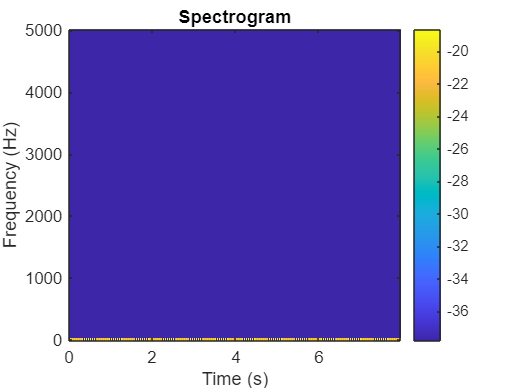

% Example: Filter Coefficients
b = B;  % Example filter coefficients (numerator)
a = A;                   % Example filter coefficients (denominator)

% Save numerator coefficients
save('numerator_coefficients.txt', 'b', '-ascii');

% Save denominator coefficients
save('denominator_coefficients.txt', 'a', '-ascii');

% Save as a PDF with minimal white space
exportgraphics(gcf, 'filter_response.pdf', 'ContentType', 'vector', 'BackgroundColor', 'none');